# Lab 5 Matlab Lecture

## Topic 1. Bode plots

A **Bode plot** is a graph that shows how a system **responds to different frequencies** of input. It's used to understand the frequency behavior of **linear time-invariant (LTI)** systems.

A Bode plot has **two separate plots**:

- **Magnitude Plot**: Shows how much the system amplifies or attenuates a sinusoidal input signal at each frequency. It's plotted in **decibels (dB)**.

- **Phase Plot**: Shows how much the system **shifts the phase** of the input signal. It's in **degrees (°)**.

**Decibels (dB):**

### 
$$20log_{10}^{|FRF|}$$$


The **Frequency Response Function (FRF)** and **Bode plots** are very similar with the only difference in the scale.

- **Bode Plot: decibles(dB), unitless**

- **FRF: Amplitude ratio, **unit depends on input and output

Example:


$$G(s)=\frac{1}{0.8s^2+10s+400}$$$


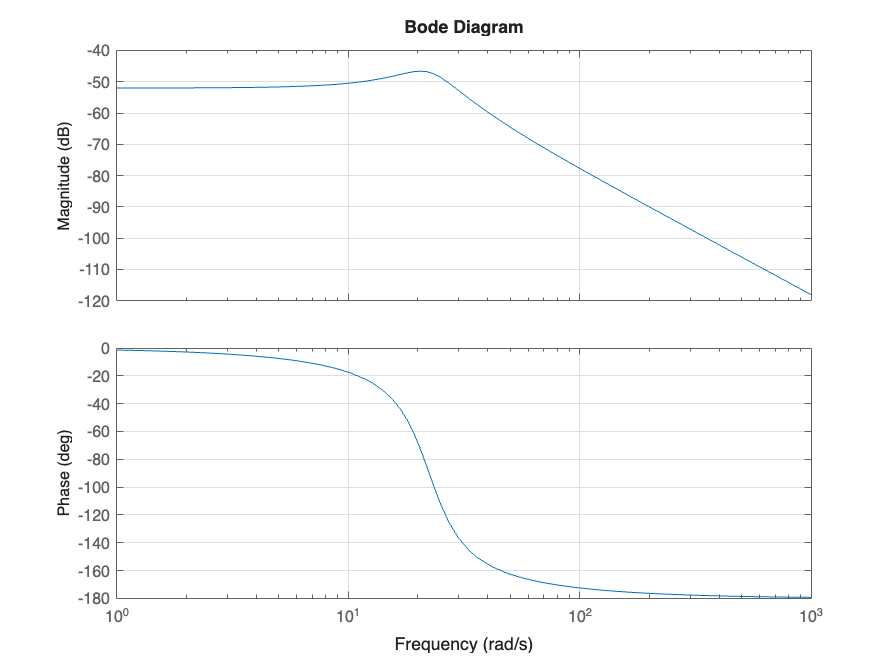

clear all
close all
clc
% Construct the transfer function
% g = tf([1],[0.8 10 400]);
% or we can do the multiplication
s = tf('s');
g = 1/(0.8*s^2+10*s+400);
% Set the frequency vector that prescribes the range we need the bode plots
% In the experiments we ran random tests in the range of 0.1 to 20 Hz. Theoretical bode works on rad/s
w = [0.1*2*pi:0.1*2*pi:20*2*pi]'; 
% Obtain the bode amplitude and phase as data points
[amp,pha] = bode(g,w);
bode(g,w)
grid on

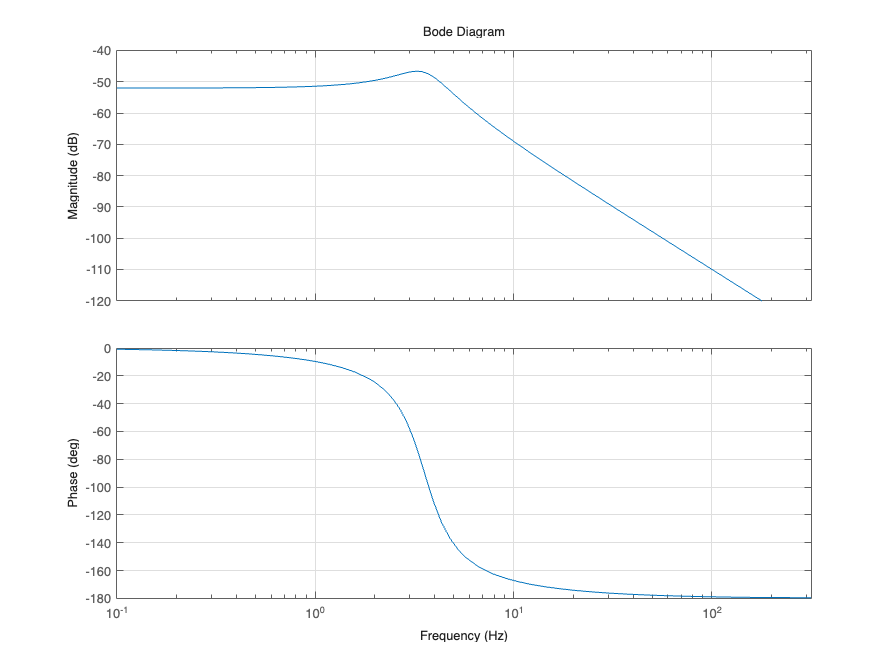

options = bodeoptions;
options.FreqUnits = 'Hz'; 
bode(g,options)
grid on;

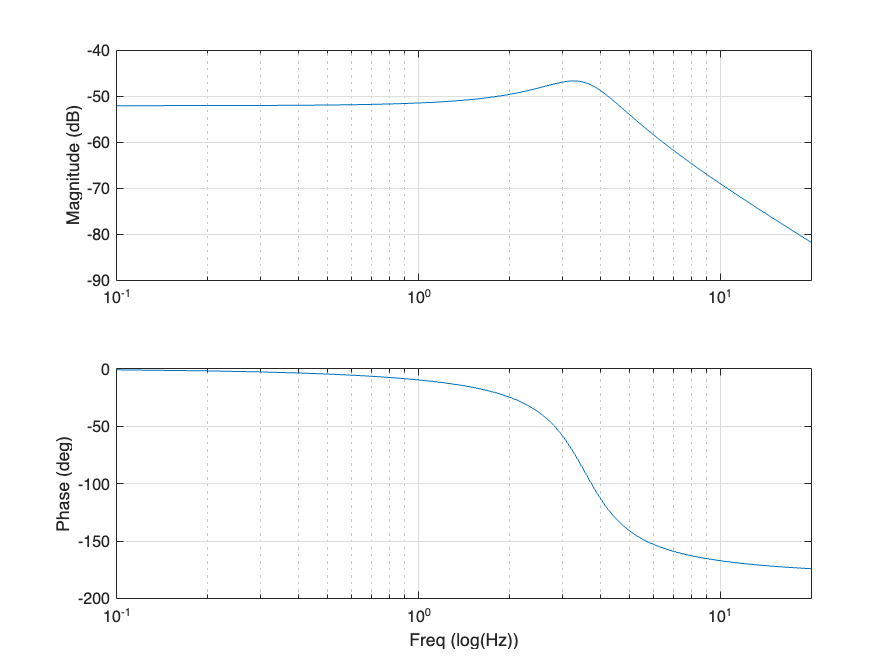

% Plotting the bode plot
figure(4)
% Converting the freq to Hz here so that you 
% directly plot your experimental bode on top of it also, be careful 
% with the dB conversion of the amplitude s 
subplot(2,1,1)     
semilogx(w/2/pi,20*log10(amp(1,:)))
ylabel('Magnitude (dB)');
grid on 
% Plot the bode pahse.                                                        
subplot(2,1,2)  
semilogx(w/2/pi,pha(1,:))%plot the bode phase in degrees
xlabel('Freq (log(Hz))');
ylabel('Phase (deg)');
grid on

## Topic 2. Gain Margin and Phase Margin

They're both **measures of how close your system is to instability** in the frequency domain.

In short:

- **Phase Margin (PM)** tells you **how much more phase lag** you can add before the system becomes unstable.

- **Gain Margin (GM)** tells you **how much you can increase the gain** before the system becomes unstable.

They give a **buffer zone** before instability occurs.

**Phase margin and gain margin are computed from the open-loop transfer function**, but they tell you about the **stability of the closed-loop system**.

## Why we use open-loop to assess closed-loop stability?

It’s because of the **Nyquist Stability Criterion**:

If the open-loop frequency response doesn’t encircle the critical point (–1), the closed-loop system is stable.

Rather than draw the Nyquist plot, we often use Bode plots and look at:

- How close the **phase** is to –180° when the **gain** is 1 → **Phase Margin**

- How close the **gain** is to 0 dB when the **phase** is –180° → **Gain Margin**

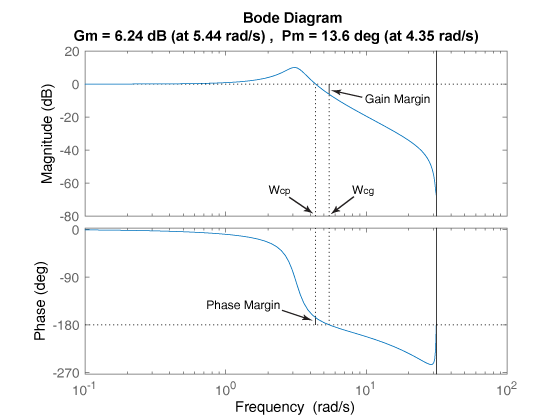

## Stability Interpretation

## Rule of Thumb

- **Phase Margin**: Aim for **45° to 60°** for good stability and damping.

- **Gain Margin**: Aim for **> 6 dB** (i.e., gain can double without instability).

Why?

**Phase margin affects ****transient response**** and ****stability robustness****.**

- If **PM is too low**:

                The system is **close to oscillating**. You get **high overshoot**, **longer settling times**, and even **instability** with small changes (e.g., modeling error, delay).

- If **PM is too high**:

                The system becomes **very sluggish**. You sacrifice **responsiveness**.

**Gain margin tells you ****how much gain variation**** you can tolerate.**

- A **GM of 6 dB** means the system can handle up to **double the gain** before going unstable:

###                 
$$20log10(\frac{V_{in}}{V_{out}})=20log 10(2)=6.02 dB$$


## Example:

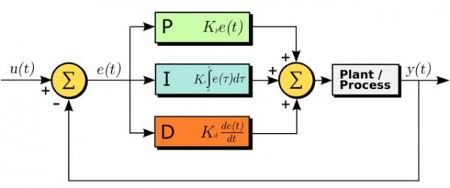

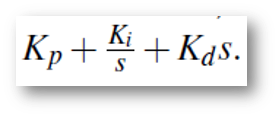

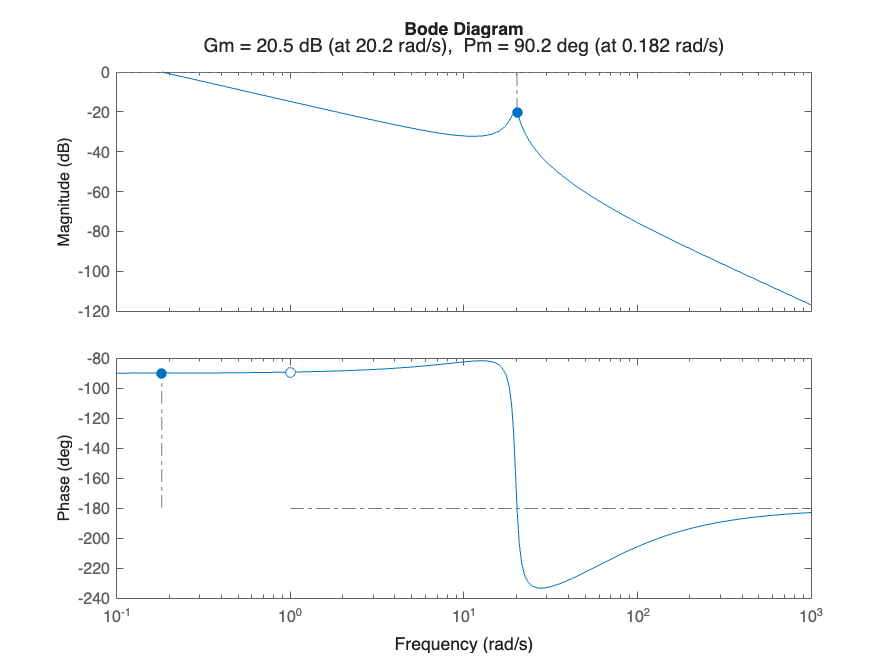


% Tutorial for determining the gain margin of the system
clear all
close all
clc

% System parameters
% m = 0.8775;     % mass [kg]
% c = 2.9123;   % damping coefficient [Ns/m]
% k = 451.39;     % stiffness [N/m]
s = tf('s');
m = 1.4;
c = 2.6;
k = 550.3;
% Controller parameters
Kp = 2;     % proportional gain % 2   
Ki = 100;     % integral gain     % 100 
Kd = 0.0;       % derivative gain

% Plant transfer function
% G=tf(1,[m c k]);
G = 1/(m*s^2+c*s+k);
% Controller transfer function
% C=tf([Kd Kp Ki],[1 0]);
C=(Kd*s^2+Kp*s+Ki)/s;
% Multiply plant and controller trasfer functions to obtain open loop transfer function
OL=G*C; 

% Plot the bode diagram and determine the phase and gain margins for the open loop transfer function
% figure(1)
margin(OL)

unstable_p = db2mag(20.5)

unstable_p = 10.5925

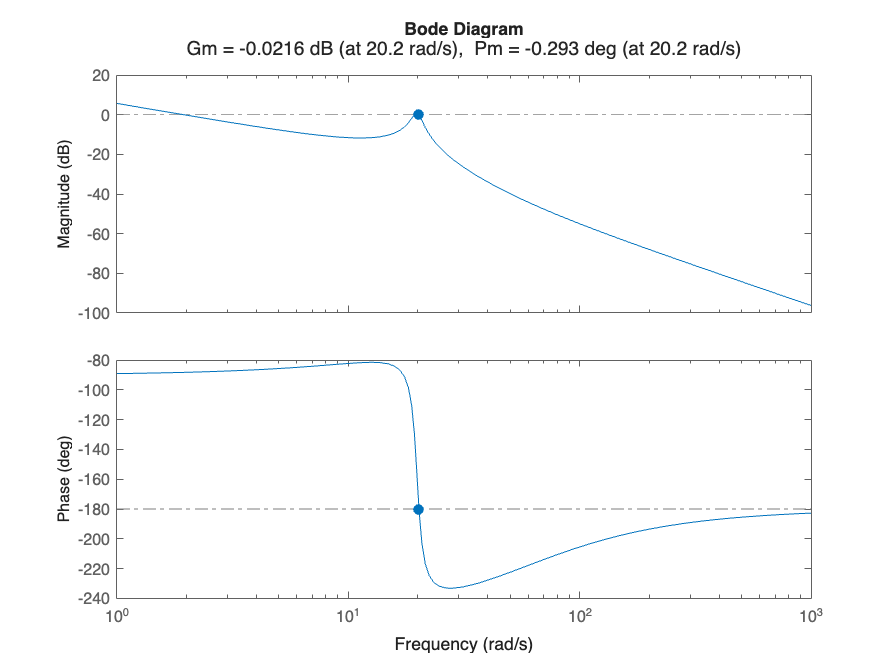

m = 1.4;
c = 2.6;
k = 550.3;
% Controller parameters
Kp = (unstable_p+0.05)*2;     % proportional gain % 2   
Ki = (unstable_p+0.05)*100;     % integral ga in     % 100 
Kd = 0.0;       % derivative gain

% Plant transfer function
% G=tf(1,[m c k]);
G = 1/(m*s^2+c*s+k);
% Controller transfer function
% C=tf([Kd Kp Ki],[1 0]);
C=(Kd*s^2+Kp*s+Ki)/s;
% Multiply plant and controller trasfer functions to obtain open loop transfer function
OL=G*C; 

% Plot the bode diagram and determine the phase and gain margins for the open loop transfer function
% figure(1)
margin(OL)

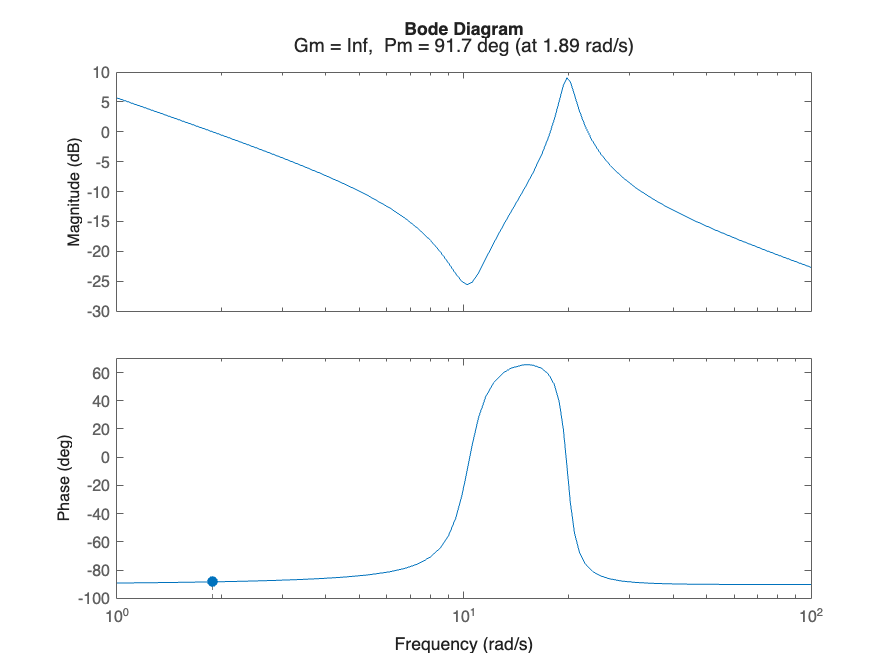

m = 1.4;
c = 2.6;
k = 550.3;
% Controller parameters
Kp = (unstable_p+0.05)*2;     % proportional gain  
Ki = (unstable_p+0.05)*100;     % integral gain
Kd = 10;       % derivative gain

% Plant transfer function
% G=tf(1,[m c k]);
G = 1/(m*s^2+c*s+k);
% Controller transfer function
% C=tf([Kd Kp Ki],[1 0]);
C=(Kd*s^2+Kp*s+Ki)/s;
% Multiply plant and controller trasfer functions to obtain open loop transfer function
OL=G*C; 

% Plot the bode diagram and determine the phase and gain margins for the open loop transfer function
% figure(1)
margin(OL)

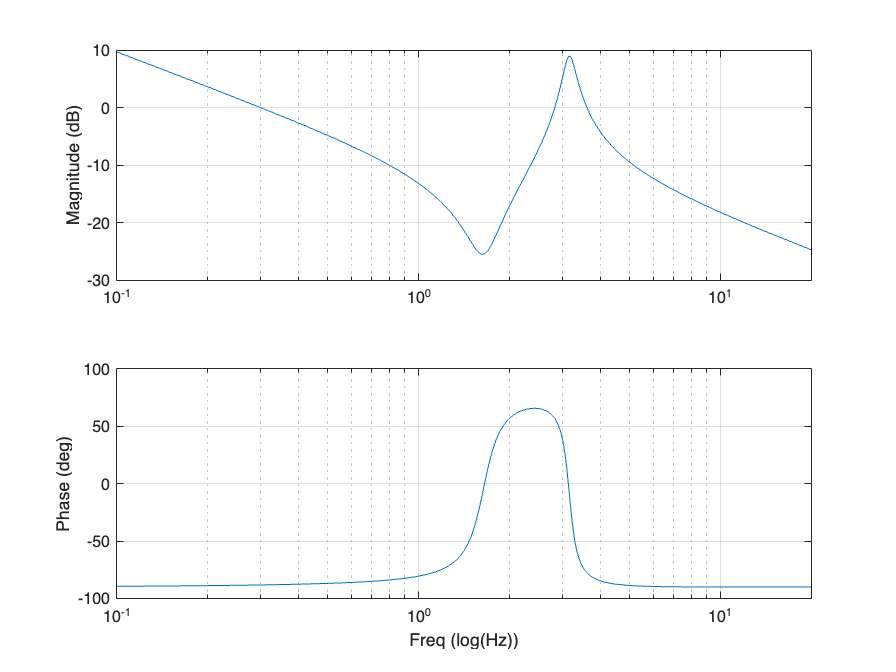


w = (0.1*2*pi:0.04*2*pi:20*2*pi)'; 
[amp,pha] = bode(OL,w); 

% Plotting the bode plot
figure(2)
% Converting the freq to Hz here so that you 
% directly plot your experimental bode on top of it also, be careful 
% with the dB conversion of the amplitude  
subplot(2,1,1)     
semilogx(w/2/pi,20*log10(amp(1,:)))
ylabel('Magnitude (dB)');
grid on 
% Plot the bode phase.                                                        
subplot(2,1,2)  
semilogx(w/2/pi,pha(1,:))%plot the bode phase in degrees
xlabel('Freq (log(Hz))');
ylabel('Phase (deg)');
grid on

# Topic 3. PID Controller

## What is PID Control?

PID stands for:

- **P**: Proportional

- **I**: Integral

- **D**: Derivative

It’s a **feedback control method** used to make a system follow a desired output (or *reference*) by minimizing the difference (called the **error**) between what you want and what you get.

PID controllers are *everywhere*—thermostats, drones, motors, robots, even espresso machines.

close all
clear all
clc

%% System parameters
m = 1.4;
c = 2.6;
k = 550.3;

w_n=sqrt(k/m); % damping ratio
eta=c/(2*m*w_n); % natural frequency
 
% Initial conditions
x0 = 0;     % initial displacement   
v0 = 0;     % initial velocity 
 
% Controller parameters
Kp = 2;     % proportional gain
Ki = 100;     % integral gain
Kd = 0.0;     % derivative gain
Tsim = 10; % Simulation Time

he transfer function from force input F(s) to displacement output X(s)is:

$G(s) = \frac{X(s)}{F(s)} = \frac{1}{m s^2 + c s + k}$�

This is the **plant** you’ll be controlling with your PID controller.

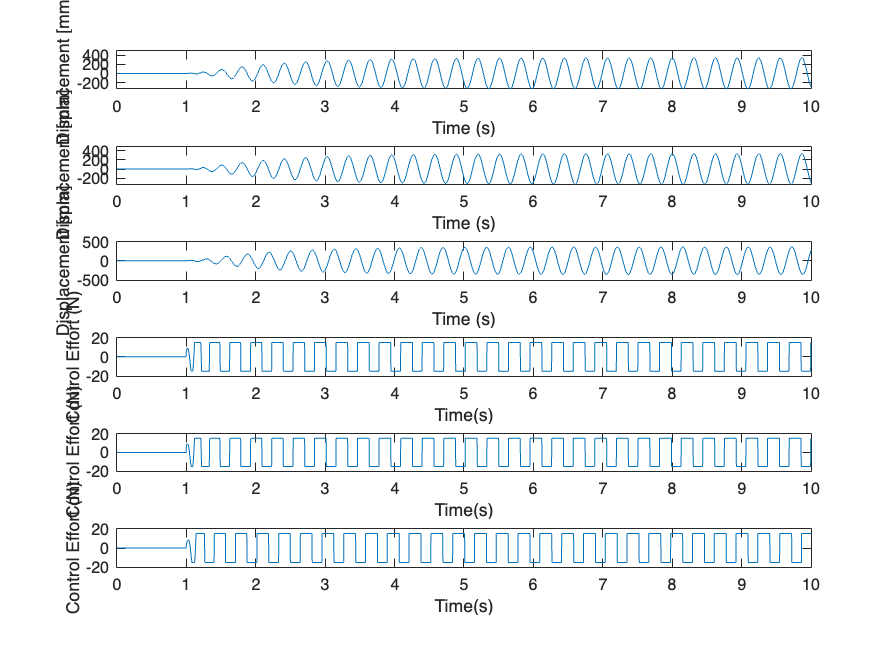

sim ('sim_control_old_version'); % call the simulation

% Plot results
figure(1)
subplot(6,1,1)
plot(x.Time,x.Data);
ylabel('Displacement [mm]')
xlabel('Time (s)')
subplot(6,1,2)
plot(x1.Time,x1.Data);
ylabel('Displacement [mm]')
xlabel('Time (s)')
subplot(6,1,3)
plot(x2.Time,x2.Data);
ylabel('Displacement [mm]')
xlabel('Time (s)')
subplot(6,1,4)
plot(c_eff.Time,c_eff.Data);
xlabel('Time(s)')
ylabel('Control Effort (N)')
subplot(6,1,5)
plot(c_eff1.Time,c_eff1.Data);
xlabel('Time(s)')
ylabel('Control Effort (N)')
subplot(6,1,6)
plot(c_eff2.Time,c_eff2.Data);
xlabel('Time(s)')
ylabel('Control Effort (N)')